# Сравнительное исследование схемы работы с автокодировщиком и без него

# Содержание исседования

Выполнено сравнение различных методов формирования пространств признаков с плохо различимыми сигналами. Исследованы различные преобразования: 

- ПКЛ, 

- ВП, 

- КВП, 

- АКВП, 

- ПФ, 

- АПФ. 

Исследованы три способа построения системы распознавания: 

- преобразование-классификатор,

- автокодировщик-классификатор (рассмотрено в рамках последней схемы с отсутствием преобразования),

- преобразование-автокодировщик-классификатор.

# Формирование данных

Возможно выбрать наборы тестовых сигналов:

- последвательность из синуса и гауссовского импульса и обратная последовательность,

- конус и сфера.

## Выбор набора данных

dataset = "Синус и гаусс"

dataset = "Синус и гаусс"

n_dim = 16

n_dim = 16

n_fvs =64

n_fvs = 64

n_fvs_tst =256

n_fvs_tst = 256

sigma_trn = 0.25

sigma_trn = 0.2500

sigma_tst = 0.25

sigma_tst = 0.2500

t_types = {'none' 'afft','fft','acwt','cwt','wt','pca'}; n_types = length(t_types);
if isequal(dataset, "Синус и гаусс")
    [rps_src, rps_shft] = create_test_signal('n_real', n_fvs, 'length', n_dim, 'sigma', sigma_trn);
    meta = repmat([0;1],n_fvs,1); % Ответы
    meta.'
    [tst_rps, tst_rps_shft] = create_test_signal('n_real', n_fvs_tst, 'length', n_dim, 'sigma', sigma_tst);
    tst_meta = repmat([0;1],n_fvs_tst,1); % тестовые ДП
    tst_meta.'
else
    warning('get rps')
end

ans =      0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1


ans =      0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1


result_crossentropy = table(zeros(n_types,1), zeros(n_types,1), zeros(n_types,1),'RowNames',t_types, 'VariableNames', {'clf','ae_clf','coder_clf'});
result_accuracy = table(zeros(n_types,1), zeros(n_types,1), zeros(n_types,1),'RowNames',t_types, 'VariableNames', {'clf','ae_clf','coder_clf'});

Осциллограммы ДП

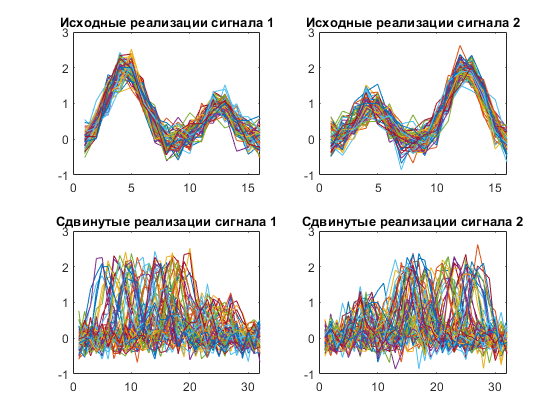

figure();
subplot(221); plot(rps_src(1:2:end,:).') % Тестовые не сдвинутые сигналы
title('Исходные реализации сигнала 1');
subplot(222); plot(rps_src(2:2:end,:).') % Тестовые не сдвинутые сигналы
title('Исходные реализации сигнала 2');
subplot(223); plot(rps_shft(1:2:end,:).') % Тестовые сдвинутые сигналы
title('Сдвинутые реализации сигнала 1');
subplot(224); plot(rps_shft(2:2:end,:).') % Тестовые сдвинутые сигналы
title('Сдвинутые реализации сигнала 2');

## Выбор параметров преобразования

transform ='acwt' 

transform = 'acwt'

system_model = SystemModel;
if strcmp(transform, 'wt'), rpfun =  @(x) system_model.transform(x, transform, 'sym2'); % выбор преобразования
elseif or(strcmp(transform, 'acwt'),strcmp(transform, 'cwt')), rpfun =  @(x) system_model.transform(x, transform, 'dtf2'); % выбор преобразования
else, rpfun =  @(x) system_model.transform(x, transform); % выбор преобразования
end
result_accuracy

result_accuracy = 7×3 table
              clf      ae_clf     coder_clf
            _______    _______    _________

    none    0.87109    0.88477     0.87695 
    afft          0          0           0 
    fft           0          0           0 
    acwt    0.88281    0.83398      0.8457 
    cwt           0          0           0 
    wt      0.79297    0.75977     0.76367 
    pca           0          0           0 


# Схема "преобразование-классификатор"

### Обучение модели

%% 1/ обучение клф без АК
system_model.pca_reset()
x = rpfun(rps_shft).';  % формирование вектора признаков
y = meta.';             % целевой вектор

cfnet = patternnet([8 4]);     % обучение классификатора
cfnet = configure(cfnet,x, y);      % нструктуры сети
cfnet.trainParam.max_fail = 10;     % число ошибок на валидационной выборке
cfnet.trainParam.showWindow = false;
[cfnet, tr_chars] = train_net(cfnet,x,y,0.08);    % обучение классификатора

thr = 0.0840

thr = 0.0882

thr = 0.0926

thr = 0.0972

thr = 0.1021

thr = 0.1072

thr = 0.1126

thr = 0.1182

thr = 0.1241

thr = 0.1303

thr = 0.1368

thr = 0.1437

thr = 0.1509

thr = 0.1584

thr = 0.1663

thr = 0.1746

thr = 0.1834

thr = 0.1925

thr = 0.2022

thr = 0.2123

thr = 0.2229

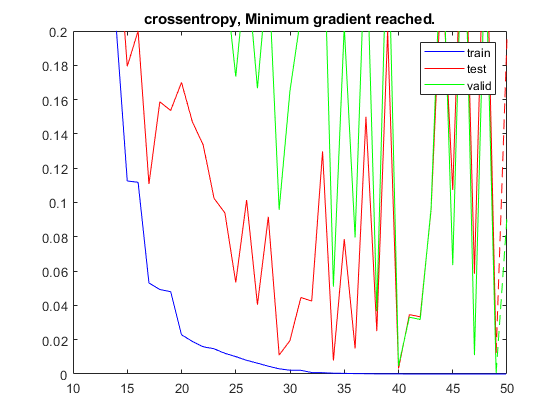

plot_performance(tr_chars);

### Матрица ошибок для обучающей выборки

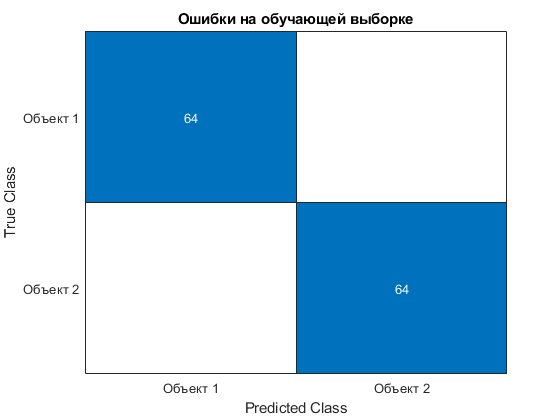

% x = rpfun(rps_shft).';  % формирование вектора признаков
% y = meta.';             % целевой вектор
pred = cfnet(x);
figure(); 
confusionchart(confusionmat((y>0.5),(pred>0.5)),{'Объект 1', 'Объект 2'}); title('Ошибки на обучающей выборке')

### Матрицы ошибок для тестовой выборки

    "Точность повышена"    "0.88281"    "->"    "0.88867"

    'Средняя абсолютная ошибка'    [0.1092]

    'Перекрестная энтропия'    [1.1946]



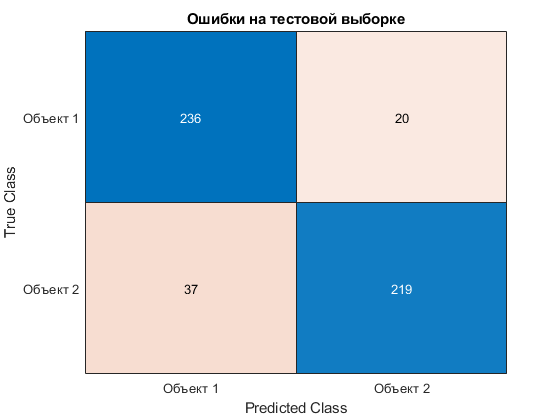

x = rpfun(tst_rps_shft).';
y = tst_meta.';
result_accuracy{transform,'clf'} = update_accuracy(...
    cfnet, x, y, result_accuracy{transform,'clf'});

# Обучение автокодировщика

%% 1/ обучение клф без АК
system_model.pca_reset()
x_ac_in = rpfun(rps_shft).';  % формирование вектора признаков
if string(transform)=="pca"
    x_ac_out = RPTools.pca(rps_src).';
else
    x_ac_out = rpfun(rps_src).';
end
ac_config = [8, 4, 8];
acnet = feedforwardnet(ac_config); acnet = configure(acnet,x_ac_in, x_ac_out);
acnet.layers{end}.transferFcn = 'tansig';   
acnet.trainParam.max_fail = 10; 
acnet.trainParam.showWindow = false;
[acnet, tr_chars]  = train_net(acnet,x_ac_in,x_ac_out,0.05);

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


thr = 0.0525

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


thr = 0.0551

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


thr = 0.0579

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


thr = 0.0608

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


thr = 0.0638

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


thr = 0.0670

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


thr = 0.0704

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


thr = 0.0739

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


thr = 0.0776

NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


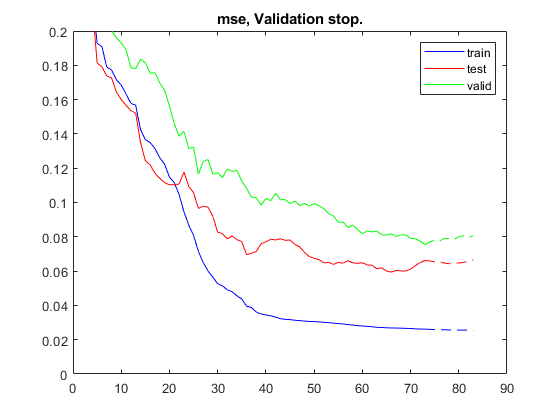

plot_performance(tr_chars);

# Схема "преобразование-автокодировщик-классификатор"

## Обучение классификатора

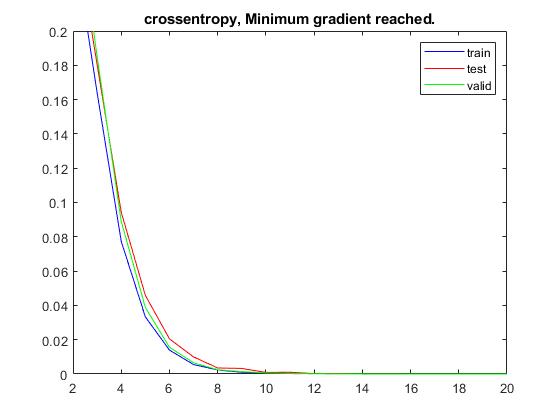

y = meta.';             % целевой вектор

cf_config = 2;
cfnet = patternnet(cf_config);     % обучение классификатора
% cfnet = configure(cfnet,x_ac_out, y);      % настройка структуры сети
% cfnet.trainParam.max_fail = 10;     % число ошибок на валидационной выборке
% cfnet.trainParam.showWindow = false;
[cfnet, tr_chars] = train_net(cfnet,x_ac_out,y,0.05);    % обучение классификатора
plot_performance(tr_chars);

### Матрица ошибок для обучающей выборки

% x = rpfun(rps_shft).';
% y = meta.';             % целевой вектор
% pred = cfnet(acnet(x));     % последовательность из АК и классификатора
% figure();
% confusionchart(confusionmat((y>0.5),(pred>0.5)),{'Объект 1', 'Объект 2'});
% title('Ошибки на обучающей выборке')

### Матрицы ошибок для тестовой выборки

    'Текущая точность'    [0.7930]

    'Средняя абсолютная ошибка'    [0.2074]

    'Перекрестная энтропия'    [2.5722]



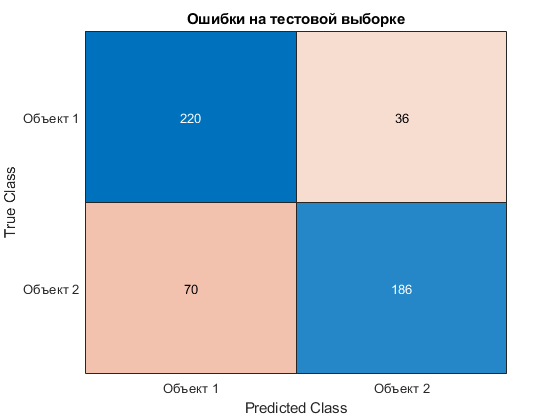

x = rpfun(tst_rps_shft).';
y = tst_meta.';
result_accuracy{transform,'ae_clf'} = update_accuracy(...
    cfnet, acnet(x), y, result_accuracy{transform,'ae_clf'});

# Схема "преобразование-кодировщик-классификатор"

## Обучение классификатора на выходах кодировщика

% формирование кодера
[~, encoder_split] = min(ac_config);
encoder_config = ac_config(1:encoder_split);
codenet = feedforwardnet(encoder_config(1:end-1));
codenet = configure(codenet,x_ac_in,randn(encoder_config(end),size(x_ac_in,2)));
codenet.layers{end}.transferFcn = 'tansig';   codenet.trainParam.max_fail = 10;
codenet.IW(:) = acnet.IW(1:encoder_split);
for from_l = 1:encoder_split
    for to_l = 1:(encoder_split)
        codenet.LW(to_l, from_l) = acnet.LW(to_l, from_l);
    end
end
codenet.b(:) = acnet.b(1:encoder_split);

x = codenet(rpfun(rps_shft).');
y = meta.';             % целевой вектор

cf_config = [];
cfnet = patternnet(cf_config);     % обучение классификатора
cfnet = configure(cfnet,x, y);      % настройка структуры сети
cfnet.trainParam.max_fail = 10;     % число ошибок на валидационной выборке
cfnet.trainParam.showWindow = false;
[cfnet, tr_chars] = train_net(cfnet,x,y,0.05);    % обучение классификатора

thr = 0.0525

thr = 0.0551

thr = 0.0579

thr = 0.0608

thr = 0.0638

thr = 0.0670

thr = 0.0704

thr = 0.0739

thr = 0.0776

thr = 0.0814

thr = 0.0855

thr = 0.0898

thr = 0.0943

thr = 0.0990

thr = 0.1039

thr = 0.1091

thr = 0.1146

thr = 0.1203

thr = 0.1263

thr = 0.1327

thr = 0.1393

thr = 0.1463

thr = 0.1536

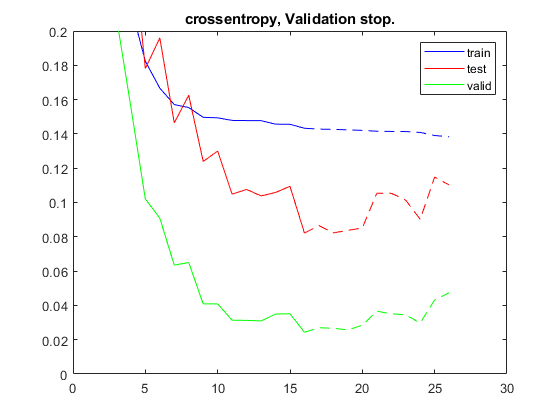

plot_performance(tr_chars);

### Матрица ошибок для обучающей выборки

x = rpfun(rps_shft).';
y = meta.';             % целевой вектор
%% доработатать соединение усеченного автокодировщика и классификатора
pred = cfnet(codenet(x));     % последовательность из АК и классификатора

### Матрицы ошибок для тестовой выборки

    'Текущая точность'    [0.8008]

    'Средняя абсолютная ошибка'    [0.2181]

    'Перекрестная энтропия'    [0.5655]



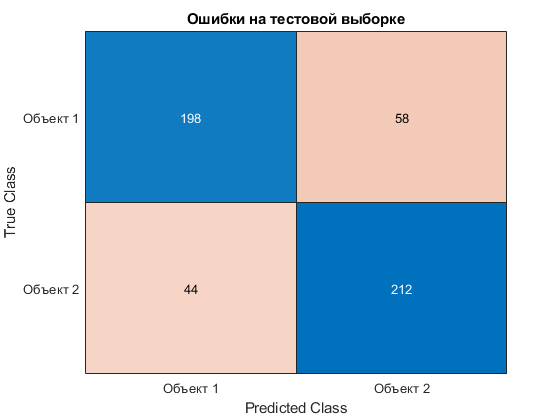

x = rpfun(tst_rps_shft).';
y = tst_meta.';
result_accuracy{transform,'coder_clf'} = update_accuracy(...
    cfnet, codenet(x), y, result_accuracy{transform,'coder_clf'});

# Приложение 1. Служебные функции

## Примеры тестовых сигналов

% [rps_src, rps_shft] = create_test_signal('n_real', 4, 'length', 16, 'sigma', 0.1);
% figure();
% subplot(211); plot(rps_src(1:2:end,:).') % Тестовые не сдвинутые сигналы
% title('Исходные реализации сигнала 1');
% subplot(212); plot(rps_src(2:2:end,:).') % Тестовые не сдвинутые сигналы
% title('Исходные реализации сигнала 2');
% figure();
% subplot(211); plot(rps_shft(1:2:end,:).') % Тестовые сдвинутые сигналы
% title('Сдвинутые реализации сигнала 1');
% subplot(212); plot(rps_shft(2:2:end,:).') % Тестовые сдвинутые сигналы
% title('Сдвинутые реализации сигнала 2');
% clear rps_shft rps_src


## Функции

function [rps_src, rps_shifted] = create_test_signal(varargin)
    signal_length = get_value(varargin, 'length', 32);
    sigma_noise = get_value(varargin, 'sigma', 0);
    n_realizations = get_value(varargin, 'n_real', 16);
    
    x_axis = linspace(-0.99*pi, 0.99*pi, ceil(signal_length/2));        % ось времени
    signal_cos = cos(x_axis)+1;                                         % фрагмент из косинуса
    signal_gauss = gaussmf(x_axis,[pi/3, 0]);                           % фрагмент из гаусса
    rps = [signal_cos, signal_gauss; signal_gauss, signal_cos];         % формирование базового сигнала 
    if size(rps,2)>signal_length, rps(:, signal_length+1:end)=[]; end   % удалить возникшие лишние отсчёты
    
%     rps_src = RPTools.add_noise(rps, [], sigma_noise, n_realizations, 1);   % не смещенные реализации
%     rps_shifted = RPTools.add_noise(rps, [], sigma_noise, n_realizations, 2);   % смещенные реализации
    
    % =======================
    multiplier = 2;
    [n_rps, dim_rp] = size(rps);
    total_samples = n_rps*n_realizations;
    % временные сдвиги
    max_shift = dim_rp*(multiplier-1);      % максимальный временной сдвиг
    r_start  = 1 + ...
        (floor(max_shift * rand(total_samples,1))); % формирование матрицы со значениями случайных сдвигов 0.1*ones(total_samples,1))); 
    r_stop   = r_start + dim_rp - 1;        % конечные индексы
    sigma_mix = (max(sigma_noise)-min(sigma_noise))*rand(total_samples,1,'like', rps)+...
        min(sigma_noise); % дисперсии равномерно распределены от сигма мин до сигма макс
    % формирование выборок с реализациями шума (длина окна больше длины исходных ДП в целое
    % число раз
    rps_src = randn( total_samples, dim_rp, 'like', rps ) .* sigma_mix;
    rps_shifted = randn( total_samples, dim_rp*ceil(multiplier), 'like', rps ); % ш. выборки
    rps_shifted = rps_shifted .* sigma_mix;   % настройка СКО шума
    % Прибавляем к шумовым выборкам случайно сдвинутый портрет
    for i = 1 : total_samples               % цикл по всем реализациям
        rps_src(i,:) = ...
                rps_src(i,:) + ...
                rps(mod(i-1, n_rps)+1,:);
        rps_shifted(i, r_start(i):r_stop(i)) = ...
                rps_src(i, :);
    end
    
    
end

function h = plot_performance(chars)
    h = figure(); 
    if chars.best_epoch
        x = 1:chars.best_epoch+1;
        plot(x, chars.perf(x), 'b', x, chars.tperf(x), 'r', x, chars.vperf(x), 'g'); hold on
    end
    x = chars.best_epoch+1:chars.num_epochs+1;
    plot(x, chars.perf(x), '--b', x, chars.tperf(x), '--r', x, chars.vperf(x), '--g');
    ylim([0 0.2])
    title([chars.performFcn,', ',chars.stop])
    legend('train','test','valid');

end

% поиск значения именнованного параметра по его имени
function parameter_value = get_value(arg_in, parameter_name, varargin)
%get_value Функция выполняет поиск имени параметра и выводит его значение
%   Аргументы:
%   arg_in - массив ячеек с последовательно идущими именами и значениями параметров - можно вводить varargin
%   parameter_name - строковое значение имени параметра, значение которого требуется найти
%   varargin - третьим элементом может быть задано значение параметра по умолчанию.
%   KeywordArguments(varargin, 'Parameter_to_find', 69) % 69 будет присвоено, если параметра нет в varargin
    i = find(strcmp(parameter_name,arg_in),1);
    if isempty(i)
        if nargin == 3
            parameter_value = varargin{1};
        else 
            error(['Параметр ' parameter_name ' не найден в вводе'])
        end
    elseif length(i)==1
        parameter_value = arg_in{i+1};    %
    else
        error(['Имя параметра ' parameter_name ' найдено несколько раз.'])
    end
end

function [varargout] = update_accuracy(clf, x, y, varargin)
    if nargin>=4, acc_old = varargin{1};
    else, acc_old = 0; 
    end
    pred = clf(x);
    conf_mx = confusionmat((y>0.5),(pred>0.5));
    if nargin==5, crossentropy_old = varargin{2}; 
    else, crossentropy_old = perform(clf,y,pred);
    end
    acc_new = sum(conf_mx(eye(length(conf_mx))==1),'all')/sum(conf_mx,'all');
    if acc_new>=acc_old
        disp(["Точность повышена" num2str(acc_old) '->' num2str(acc_new)]);
        crossentropy_new = perform(clf,y,pred);
    else
        disp({'Текущая точность',acc_new})
        acc_new = acc_old; crossentropy_new = crossentropy_old;
    end
    disp({'Средняя абсолютная ошибка',mean(abs(pred-y))}); disp({'Перекрестная энтропия',crossentropy_new});
    figure(); 
    confusionchart(conf_mx,{'Объект 1', 'Объект 2'});
    title('Ошибки на тестовой выборке')
    if nargout>=1, varargout{1} = acc_new;          end
    if nargout>=2, varargout{2} = crossentropy_new; end
end

function [r_net, chars] = train_net(net,x,y,varargin)
    if nargin==4, thr = varargin{1}; else, thr = 1; end
    for i=1:64
        net = configure(net,x, y);      % нструктуры сети
        net.trainParam.max_fail = 10;     % число ошибок на валидационной выборке
        net.trainParam.showWindow = false;
        
        [r_net, chars] = train(net,x,y,'useGPU','yes');    % обучение классификатора
        if max([chars.vperf(chars.best_epoch+1), chars.tperf(chars.best_epoch+1), chars.perf(chars.best_epoch+1)])<=thr
            break
        else, thr=thr*1.05
        end
    end
    if i==16, disp('Stop iteration'); end
end